% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

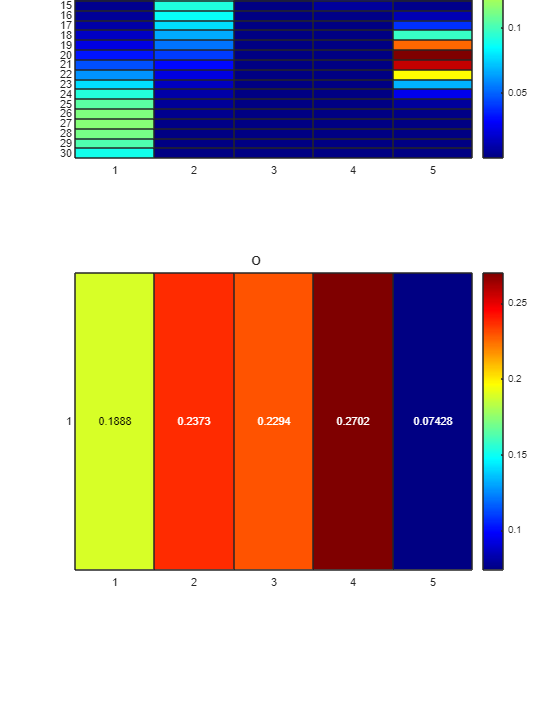

k = 5;
d = 30;

options.method = "random";
options.lambda = 5;

[T, O, pi, k, d] = generateHMM(k, d, 1, options);

figure('Renderer', 'painters', 'Position', [10 10 900 1200])


subplot(3, 1, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(3, 1, 2);
h = heatmap(O, Colormap=jet());
h.Title = 'O';

subplot(3, 1, 3);
h = heatmap(pi, Colormap=jet());
h.Title = '\pi';

Calculate true joint probability tensor $$P_3^\infty$$

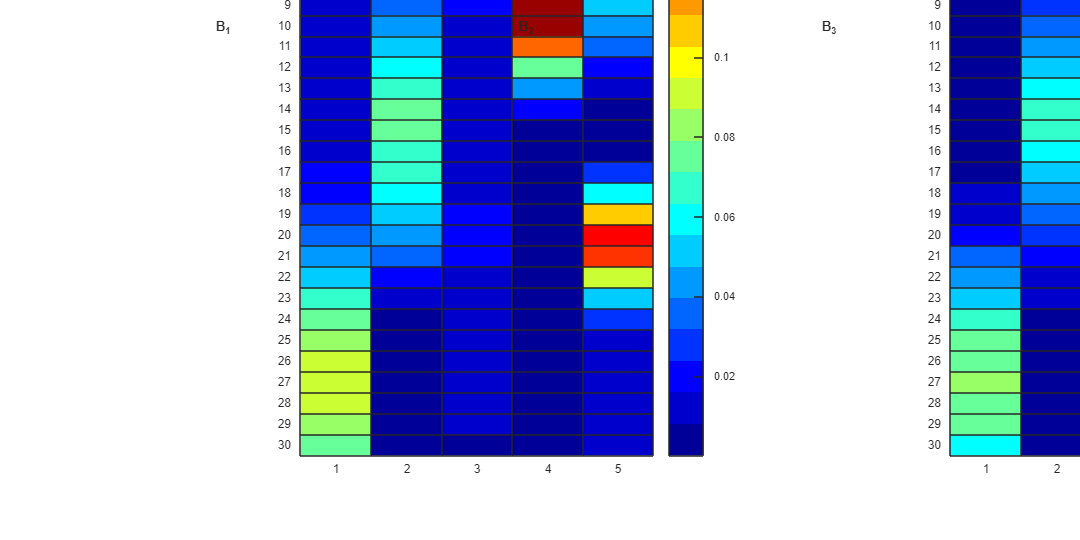


D = {};
D{1} = Stochasticize(O * diag(pi) * T' * inv(diag(T * pi')));
D{2} = O;
D{3} = Stochasticize(O * T);

P3_inf = cpdgen(D)/k;

PlotFactorMatrices(D);

Generate the joint probability tensor (JPT) $P_3^n$ by sampling n datasamples from the HMM matrices


T_seq = 1e5;

[seq, states] = generate_hmm_sequence(T, O, pi, T_seq);

tic
[P3_n, convergence] = estimate_joint_prob(seq, d, P3_inf);
toc

Elapsed time is 0.072658 seconds.



alpha = 1e-3;
% P3_n = laplacian_smoothing_mle(P3_n, alpha);


Plot the convergence of the sampled JPT

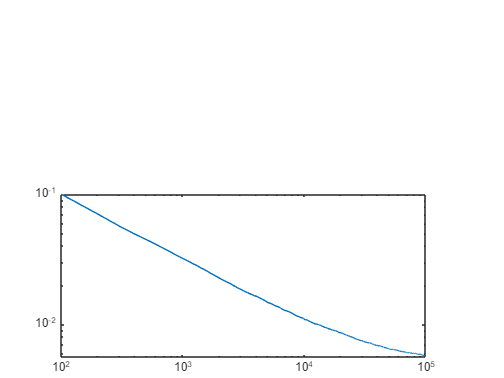

figure()
loglog(linspace(0, T_seq, length(convergence)), convergence)

Apply structured ridge regression CPD to obtain factor matrices.


options.lambda1 = 0.0001;
options.lambda2 = 0.0001;

options.maxIter = 50;
options.tol = 1e-5;

options.mode = "Structured";
[B1, B2, B3, output] = cpd_als_extended(P3_inf, k, options);

Converged at iteration 18


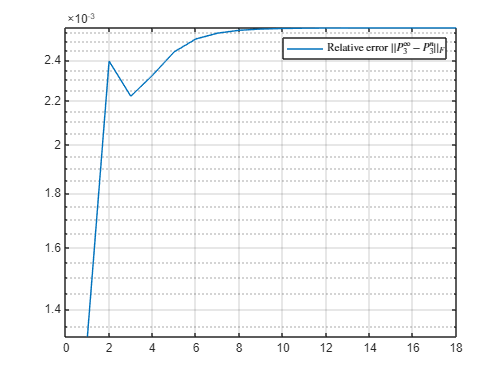


set(groot, 'defaultLegendInterpreter','latex');

figure()
semilogy(output.iters, output.relerr_tensor)
legend("Relative error $||P_3^\infty - P_3^n||_F$")
grid on;



[T_hat, O_hat, pi_hat] = remove_hmm_permutation_transition(T, Stochasticize(pinv(B2) * B3), B2, findStationaryDistribution(Stochasticize(pinv(B2) * B3)'));
norm(T-T_hat, "fro") + norm(O-O_hat, "fro")

ans = 0.1434

plotHMMError(T, T_hat, O, O_hat, pi, pi_hat);



options.maxIter = 500;
options.tol = 1e-10;


lambdas = [khatri_rao([1e-6 1e-5 1e-4]', [1 2 3 4 5 6 7 8 9]')' khatri_rao(1e-3, [1 2 3 4 5]')'];
% lambdas = khatri_rao([1e-6 1e-5]', [1 2 3 4 5 6 7 8 9]')';
% lambdas = linspace(1e-5, 1e-1, 10);
% lambdas = 1e-5 * ones(1, 10);
modes = ["Regular", "Ridge", "Structured", "Proximal", "Prior", "Smooth"];

lamIter = length(lambdas);
modIter = length(modes);

costs = zeros(length(lambdas), length(modes));

for i = 1:modIter
    options.mode = modes(i);
    for j = 1:lamIter
        options.lambda1 = lambdas(j);
        options.lambda2 = lambdas(j);

        [B1, B2, B3, output] = cpd_als_extended(P3_inf, k, options);
        
        [T_hat, O_hat, pi_hat] = remove_hmm_permutation_transition(T, Stochasticize(pinv(B2) * B3), B2, findStationaryDistribution(Stochasticize(pinv(B2) * B3)'));
        costs(j, i) = norm(T-T_hat, "fro")+ norm(O-O_hat, "fro");
    end
end

Converged at iteration 60
Converged at iteration 57
Converged at iteration 73
Converged at iteration 60
Converged at iteration 60
Converged at iteration 61
Converged at iteration 74
Converged at iteration 61
Converged at iteration 63
Converged at iteration 61
Converged at iteration 55
Converged at iteration 62
Converged at iteration 61
Converged at iteration 69
Converged at iteration 59
Converged at iteration 57
Converged at iteration 79
Converged at iteration 60
Converged at iteration 65
Converged at iteration 65
Converged at iteration 59
Converged at iteration 61
Converged at iteration 58
Converged at iteration 63
Converged at iteration 61
Converged at iteration 63
Converged at iteration 51
Converged at iteration 62
Converged at iteration 53
Converged at iteration 62
Converged at iteration 53
Converged at iteration 59
Converged at iteration 65
Converged at iteration 66
Converged at iteration 65
Converged at iteration 62
Converged at iteration 61
Converged at iteration 99
Converged at

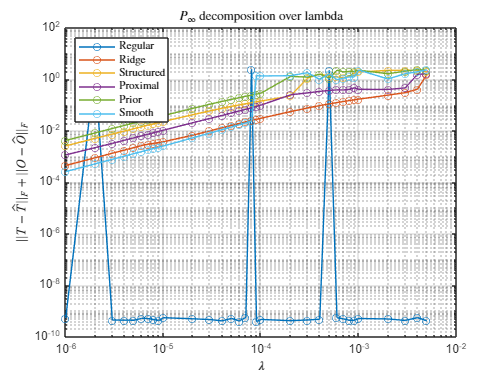


figure()
loglog(lambdas, costs', '-o')
grid on;
title(["$P_{\infty}$ decomposition over lambda"], "Interpreter","latex")
legend(modes,'Location', 'northwest');
xlabel("$\lambda$", 'Interpreter','latex', 'FontWeight','bold')
ylabel("$||T - \hat{T}||_F + ||O - \hat{O}||_F$", 'Interpreter','latex', 'FontWeight','bold')

% options.maxIter = 500;
% options.tol = 1e-10;
% 
% 
% lambdas = [khatri_rao([1e-6 1e-5 1e-4]', [1 2 3 4 5 6 7 8 9]')' khatri_rao(1e-3, [1 2 3 4 5]')'];
% % lambdas = khatri_rao([1e-6 1e-5 1e-4]', [1 2 3 4 5 6 7 8 9]')';
% % lambdas = linspace(1e-5, 1e-1, 10);
% % lambdas = 1e-5 * ones(1, 10);
% modes = ["Regular", "Ridge", "Structured", "Proximal", "Prior", "Smooth"];
% 
% lamIter = length(lambdas);
% modIter = length(modes);
% 
% costs = zeros(length(lambdas), length(lambdas), length(modes));
% 
% for i = 1:modIter
%     options.mode = modes(i);
% 
%     for j = 1:lamIter
%         for l = 1:lamIter
%             options.lambda1 = lambdas(j);
%             options.lambda2 = lambdas(l);
% 
%             [B1, B2, B3, output] = cpd_als_extended(P3_n, k, options);
% 
%             [T_hat, O_hat, pi_hat] = remove_hmm_permutation_transition(T, Stochasticize(pinv(B2) * B3), B2, findStationaryDistribution(Stochasticize(pinv(B2) * B3)'));
%             costs(j, l, i) = norm(T-T_hat, "fro")+ norm(O-O_hat, "fro");
%         end
%     end
% end
% 
% 
% for i = 1:modIter
%     figure()
%     surf(lambdas, lambdas, costs(:, :, i))
%     title(modes(i))
%     hold on
% end



% figure()
% bar3(costs')
% set(gca,'XTickLabel',modes)
% set(gca,'YTickLabel',lambdas)
% ylabel("$\lambda$", 'Interpreter','latex', 'FontWeight','bold')
% zlabel("$||T - \hat{T}||_F + ||O - \hat{O}||_F$", 'Interpreter','latex', 'FontWeight','bold')

% figure()
% loglog(lambdas, costs, '-o')
% grid on;
% % ylim([0.1 0.5]);
% legend(modes,'Location', 'northwest');
% xlabel("$\lambda$", 'Interpreter','latex', 'FontWeight','bold')
% ylabel("$||T - \hat{T}||_F + ||O - \hat{O}||_F$", 'Interpreter','latex', 'FontWeight','bold')

